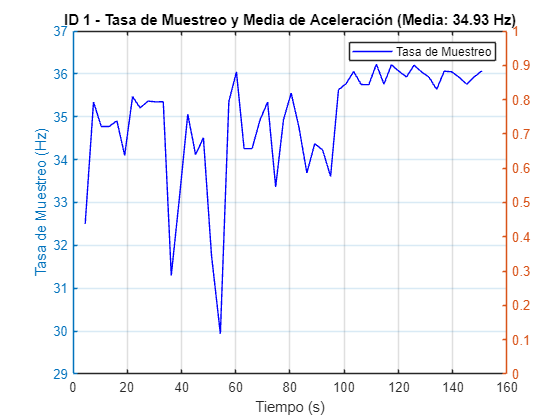

Bias calculado mediante min/max para ID 1:


   22.2810   21.1750   26.6560



Bias calculado mediante media para ID 1:


   33.9744   29.9549    9.0266



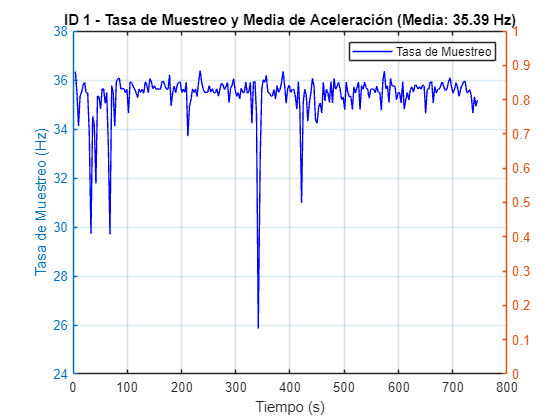

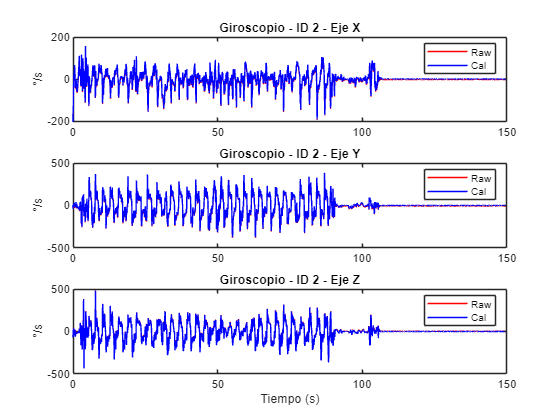

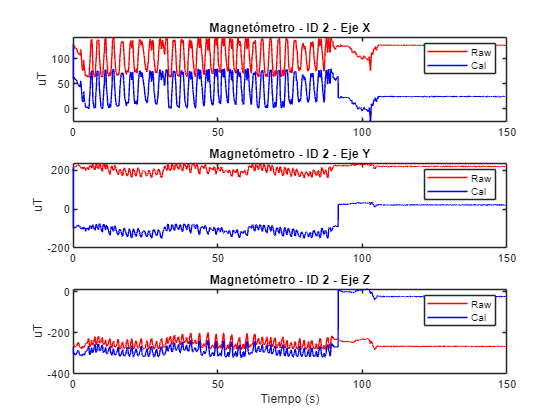

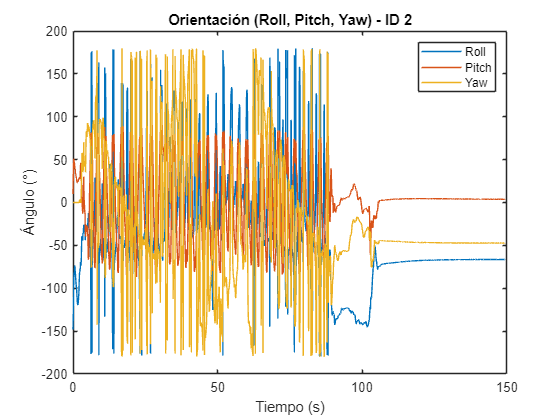

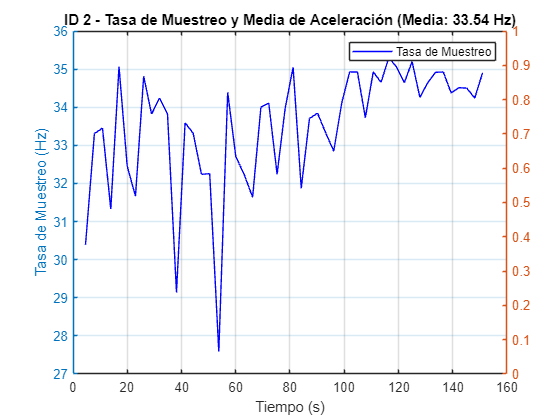

Bias calculado mediante min/max para ID 2:


  103.1940  199.2760 -240.7370



Bias calculado mediante media para ID 2:


  112.6002  209.6551 -255.5363



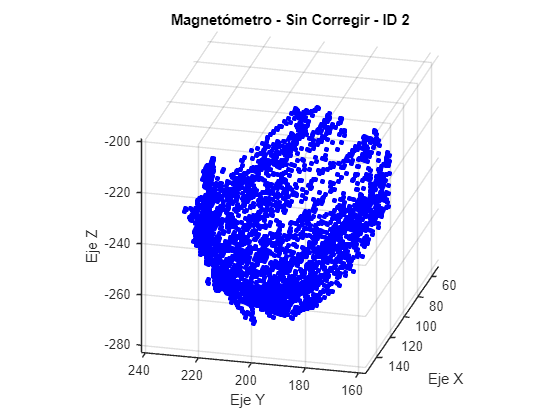

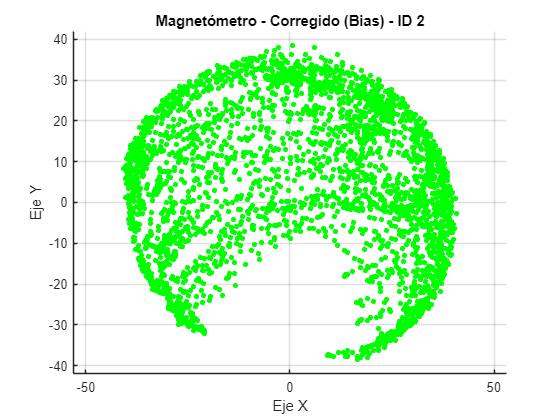

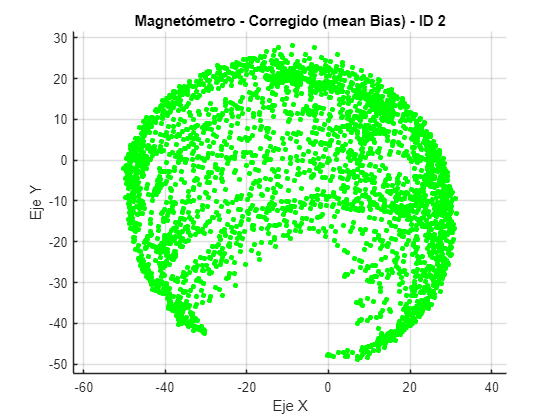

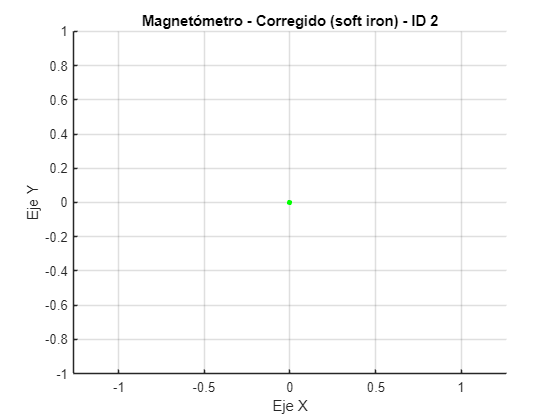

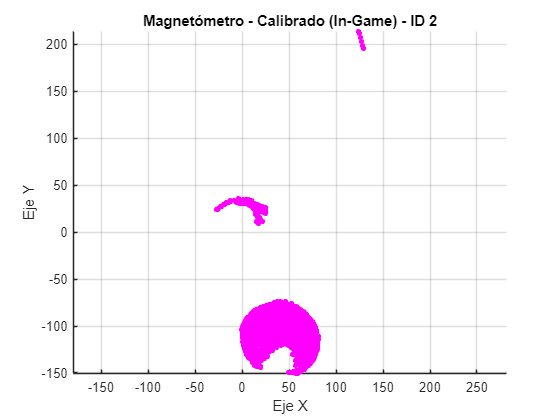

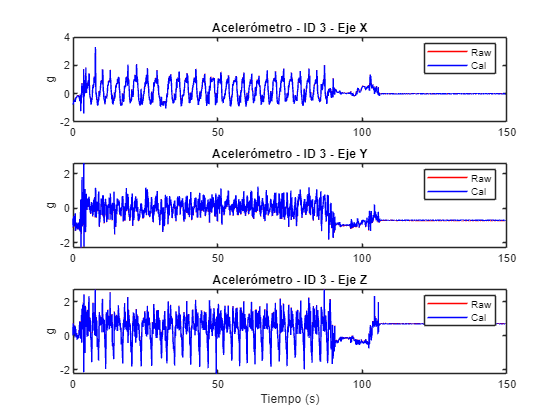

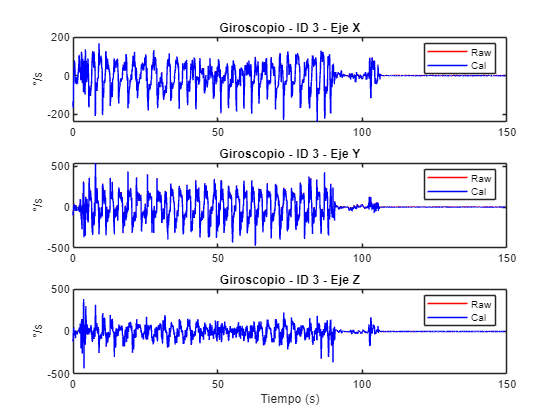

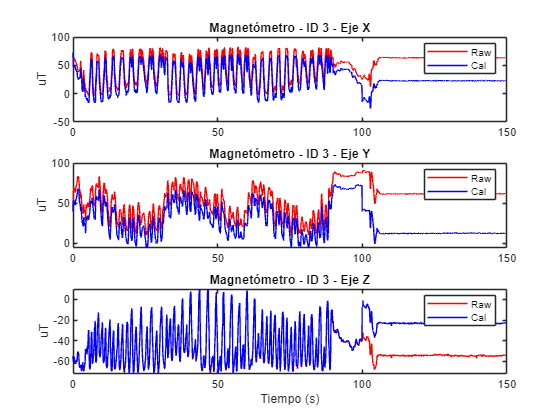

Bias calculado mediante min/max para ID 3:


   39.6690   50.6590  -31.3110



Bias calculado mediante media para ID 3:


   49.1887   54.1909  -47.8399



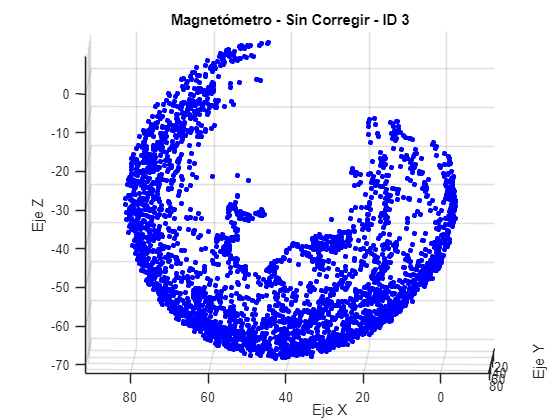

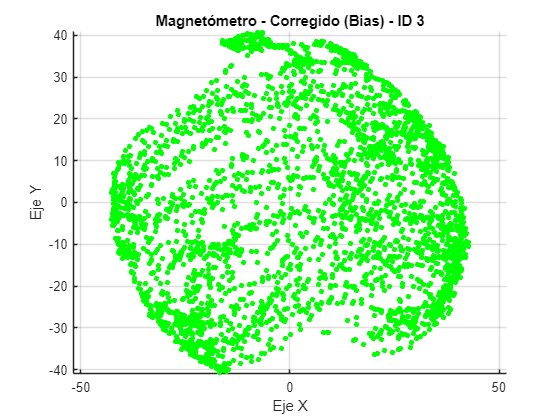

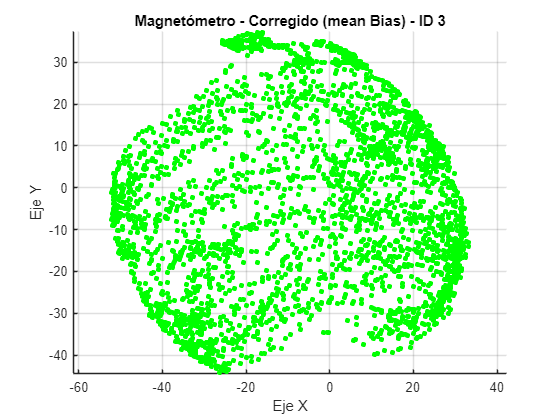

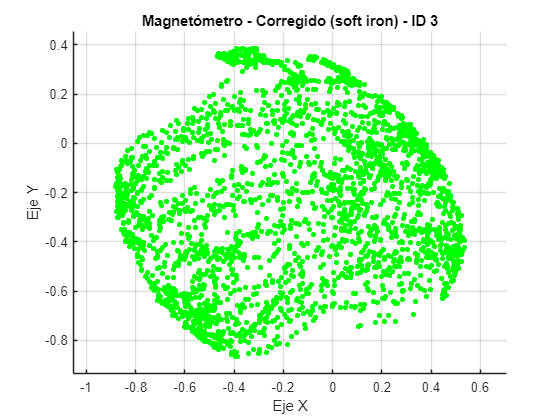

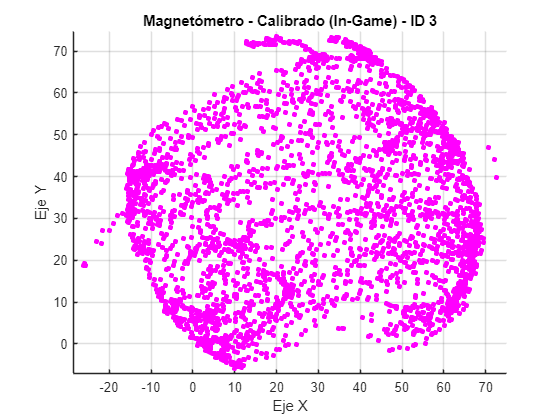

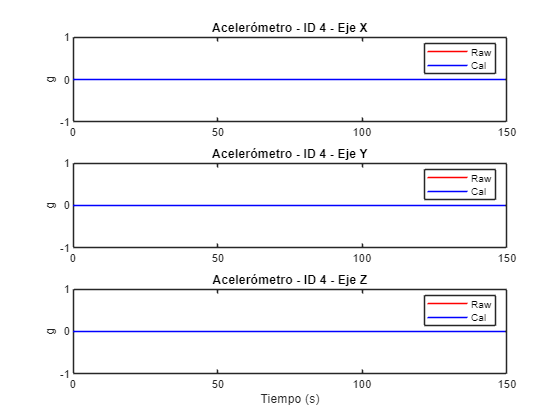

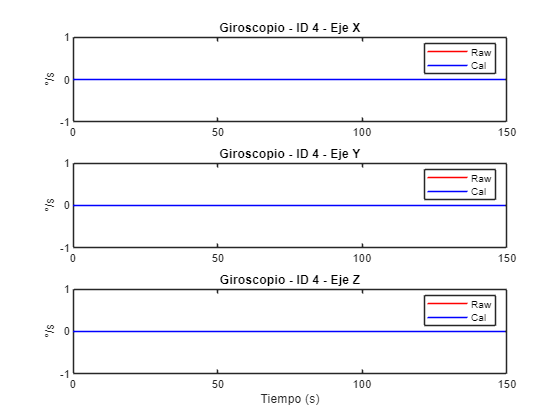

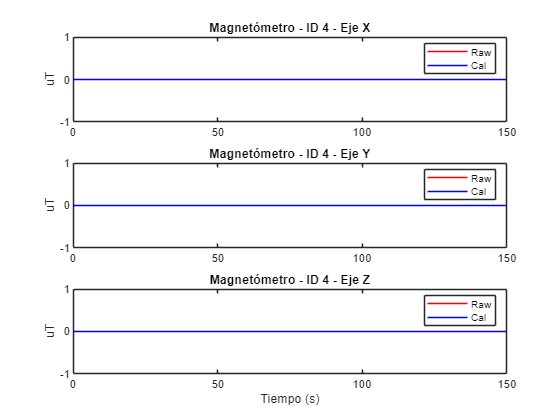

Bias calculado mediante min/max para ID 4:


     0     0     0



Bias calculado mediante media para ID 4:


     0     0     0



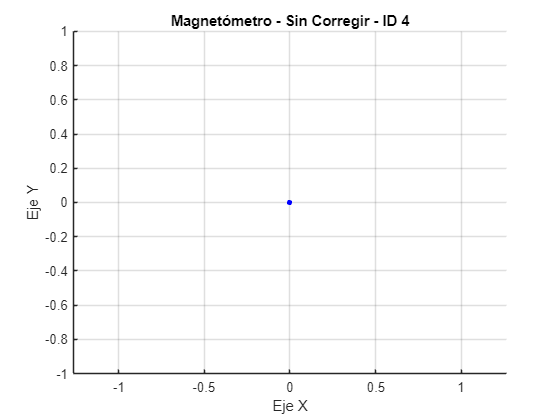

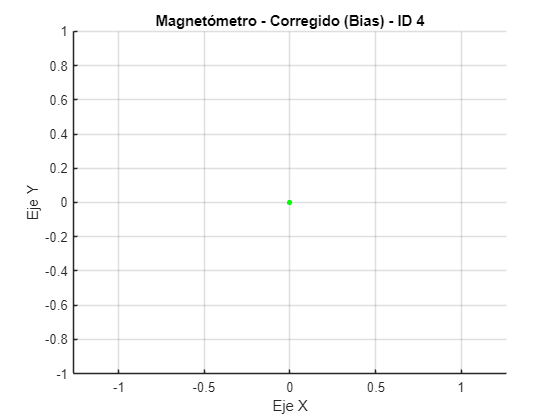

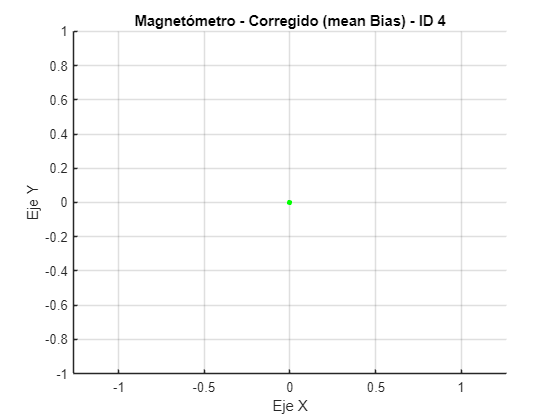

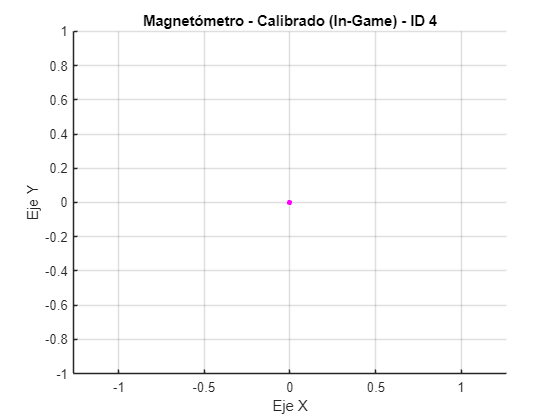

% Cambia esta línea al path de tu archivo
archivo = 'sensor3_log_extIMU5_calibred.txt';


% Leer el archivo como texto con separador ';'
data = readmatrix(archivo, 'Delimiter', ';');

% Asignar variables generales
timestamp     = data(:,1);
accel         = data(:,2:4);
gyro          = data(:,5:7);
mag           = data(:,8:10);
accel_cal     = data(:,11:13);
gyro_cal      = data(:,14:16);
mag_cal       = data(:,17:19);
orientacion   = data(:,20:22);
id            = data(:,23);

t = (timestamp - timestamp(1));

% IDs únicos presentes en el archivo
ids_unicos = unique(id);

%% ----------- Procesar por cada ID -----------
for k = 1:length(ids_unicos)
    id_actual = ids_unicos(k);
    idx = (id == id_actual);

    % Filtrar datos por ID
    t_id = t(idx);
    ts_id = timestamp(idx);
    accel_id = accel(idx,:);
    gyro_id = gyro(idx,:);
    mag_id = mag(idx,:);
    accel_cal_id = accel_cal(idx,:);
    gyro_cal_id = gyro_cal(idx,:);
    mag_cal_id = mag_cal(idx,:);
    orientacion_id = orientacion(idx,:);

    % Comparación sin calibrar vs calibrado
    plot_comparacion(t_id, accel_id, accel_cal_id, sprintf('Acelerómetro - ID %d', id_actual), 'g');
    plot_comparacion(t_id, gyro_id, gyro_cal_id, sprintf('Giroscopio - ID %d', id_actual), '°/s');
    plot_comparacion(t_id, mag_id, mag_cal_id, sprintf('Magnetómetro - ID %d', id_actual), 'uT');

    % Graficar orientación
    figure('Name', sprintf('Orientación - ID %d', id_actual));
    plot(t_id, orientacion_id);
    title(sprintf('Orientación (Roll, Pitch, Yaw) - ID %d', id_actual));
    xlabel('Tiempo (s)');
    ylabel('Ángulo (°)');
    legend('Roll', 'Pitch', 'Yaw');

    %% ----------- Frecuencia de muestreo por ID mejorada -----------
    window_size = 100;
    timestamp_id = timestamp(idx);
    accel_id = accel(idx, :);
    
    % Número de ventanas
    num_samples = length(timestamp_id);
    num_windows = floor(num_samples / window_size);
    
    % Inicializar variables
    sampling_rates = zeros(num_windows, 1);
    mean_values = zeros(num_windows, 1);
    window_times = zeros(num_windows, 1);
    
    for i = 1:num_windows
        idx_start = (i-1)*window_size + 1;
        idx_end = i*window_size;
        
        t_window = timestamp_id(idx_start:idx_end);
        a_window = accel_id(idx_start:idx_end, 1); % aceleración eje X
        
        dt = t_window(end) - t_window(1);
        sampling_rates(i) = (length(t_window)-1) / dt;
        mean_values(i) = mean(a_window);
        window_times(i) = mean(t_window);
    end
    
    T = table(window_times, sampling_rates, mean_values, ...
        'VariableNames', {'TiempoVentana', 'TasaMuestreo', 'MediaAccelX'});
    
    % Guardar en la estructura
    nombre_tabla = sprintf('ID_%d', id_actual);
    tablas_por_id.(nombre_tabla) = T;
    % Calcular valor medio total de la tasa de muestreo
    tasa_muestreo_media_total = mean(sampling_rates);

    % Opcional: graficar
    figure;
    yyaxis left
    plot(window_times, sampling_rates, '-b');
    ylabel('Tasa de Muestreo (Hz)');

    % yyaxis right
    % plot(window_times, mean_values, '-r');
    % ylabel('Aceleración Media (m/s^2)');

    xlabel('Tiempo (s)');
    title(sprintf('ID %d - Tasa de Muestreo y Media de Aceleración (Media: %.2f Hz)', ...
        id_actual, tasa_muestreo_media_total));
    legend('Tasa de Muestreo', 'Media Accel X');
    grid on;

    %% ----------- Visualización del Magnetómetro por ID -----------

    % Calcular bias del magnetómetro para este ID
    % bias_mag = mean(mag_id, 1);
    max_mag = max(mag_id);
    min_mag = min(mag_id);
    bias_mag = (max_mag+min_mag)/2;
    mag_corregido = mag_id - bias_mag;
    bias_mean_mag = mean(mag_id);
    mag_mean_corregido = mag_id - bias_mean_mag;

    disp(['Bias calculado mediante min/max para ID ' num2str(id_actual) ':']);
    disp(bias_mag);
    disp(['Bias calculado mediante media para ID ' num2str(id_actual) ':']);
    disp(bias_mean_mag);

    % Magnetómetro sin corregir
    figure('Name', sprintf('Magnetómetro - Sin Corregir - ID %d', id_actual));
    hold on; grid on; axis equal;
    title(sprintf('Magnetómetro - Sin Corregir - ID %d', id_actual));
    xlabel('Eje X'); ylabel('Eje Y'); zlabel('Eje Z');
    scatter3(mag_id(:,1), mag_id(:,2), mag_id(:,3), 15, 'b', 'filled');
    hold off;

    % Magnetómetro corregido con Bias
    figure('Name', sprintf('Magnetómetro - Corregido con Bias - ID %d', id_actual));
    hold on; grid on; axis equal;
    title(sprintf('Magnetómetro - Corregido (Bias) - ID %d', id_actual));
    xlabel('Eje X'); ylabel('Eje Y'); zlabel('Eje Z');
    scatter3(mag_corregido(:,1), mag_corregido(:,2), mag_corregido(:,3), 15, 'g', 'filled');
    hold off;

    % Magnetómetro corregido con Bias media
    figure('Name', sprintf('Magnetómetro - Corregido con mean Bias - ID %d', id_actual));
    hold on; grid on; axis equal;
    title(sprintf('Magnetómetro - Corregido (mean Bias) - ID %d', id_actual));
    xlabel('Eje X'); ylabel('Eje Y'); zlabel('Eje Z');
    scatter3(mag_mean_corregido(:,1), mag_mean_corregido(:,2), mag_mean_corregido(:,3), 15, 'g', 'filled');
    hold off;

    if id_actual >1 && id_actual < 4
        distancias = vecnorm(mag_id - bias_mag, 2, 2);
        media_d = mean(distancias);
        std_d = std(distancias);
        umbral = 1.5;  % ajustable: 2.5 sigma es común
        idx_validos = distancias < (media_d + umbral * std_d);
    
        % Filtrar datos
        mag_filtrado = mag_id(idx_validos, :);
        calibrarMagnetometro(mag_filtrado, id_actual);
    end

    % Magnetómetro corregido in-game
    figure('Name', sprintf('Magnetómetro - Calibrado (In-Game) - ID %d', id_actual));
    hold on; grid on; axis equal;
    title(sprintf('Magnetómetro - Calibrado (In-Game) - ID %d', id_actual));
    xlabel('Eje X'); ylabel('Eje Y'); zlabel('Eje Z');
    scatter3(mag_cal_id(:,1), mag_cal_id(:,2), mag_cal_id(:,3), 15, 'm', 'filled');
    hold off;

    % calibrateMagnetometer(mag_id, id_actual)

end

function plot_comparacion(t, sin_cal, cal, nombre, unidad)
    figure('Name',nombre);
    subplot(3,1,1); plot(t, sin_cal(:,1), 'r', t, cal(:,1), 'b'); title([nombre ' - Eje X']); ylabel(unidad); legend('Raw', 'Cal');
    subplot(3,1,2); plot(t, sin_cal(:,2), 'r', t, cal(:,2), 'b'); title([nombre ' - Eje Y']); ylabel(unidad); legend('Raw', 'Cal');
    subplot(3,1,3); plot(t, sin_cal(:,3), 'r', t, cal(:,3), 'b'); title([nombre ' - Eje Z']); ylabel(unidad); xlabel('Tiempo (s)'); legend('Raw', 'Cal');
end


function calibrarMagnetometro(data, id_actual)
     if size(data, 2) ~= 3
        error('La entrada debe tener 3 columnas (X, Y, Z).');
     end


    s = data';
    % Construcción de la matriz D para elipsoide
    D = [s(1,:).^2;
         s(2,:).^2;
         s(3,:).^2;
         2*s(2,:).*s(3,:);
         2*s(1,:).*s(3,:);
         2*s(1,:).*s(2,:);
         2*s(1,:);
         2*s(2,:);
         2*s(3,:);
         ones(1, size(s,2))];

    S = D * D';
    S11 = S(1:6, 1:6);
    S12 = S(1:6, 7:10);
    S21 = S12';
    S22 = S(7:10, 7:10);

    % Matriz C del artículo de Li & Griffiths
    C = [-1  1  1  0  0  0;
          1 -1  1  0  0  0;
          1  1 -1  0  0  0;
          0  0  0 -4  0  0;
          0  0  0  0 -4  0;
          0  0  0  0  0 -4];

    E = inv(C) * (S11 - S12 * (S22 \ S21));
    [E_vec, E_val] = eig(E);
    [~, idx] = max(real(diag(E_val)));
    v1 = real(E_vec(:,idx));
    if v1(1) < 0
        v1 = -v1;
    end

    v2 = -inv(S22) * S21 * v1;

    % Parámetros del elipsoide
    M = [v1(1), v1(4), v1(5);
         v1(4), v1(2), v1(6);
         v1(5), v1(6), v1(3)];
    n = v2(1:3);
    d = v2(4);

    % Corrección hard iron
    M_inv = inv(M);
    hard_corr = -M_inv * n;

    % Corrección soft iron
    F = 1;  % Magnitud esperada del campo magnético (normalizada)
    alpha = F / sqrt(n' * M_inv * n - d);
    soft_corr = real(alpha * sqrtm(M));

    data_corregida = soft_corr*(s - hard_corr);
    data_corregida_t = data_corregida';



    figure('Name', sprintf('Magnetómetro - Corregido soft iron - ID %d', id_actual));
    hold on; grid on; axis equal;
    title(sprintf('Magnetómetro - Corregido (soft iron) - ID %d', id_actual));
    xlabel('Eje X'); ylabel('Eje Y'); zlabel('Eje Z');
    scatter3(data_corregida_t(:,1), data_corregida_t(:,2), data_corregida_t(:,3), 15, 'g', 'filled');
    hold off;
end
